clearvars -except DDPG_AGENT_2000
rng(13);

%% ── 1. Generate 50 reproducible test scenarios ───────────────────────────
N = 50;

start_heights  = round(0.5 + 19.5 * rand(N,1), 1);
target_heights = round(2.0 + 16.0 * rand(N,1), 1);

T_stop  = 200;
Kp_init = 5;
Ki_init = 2.5;
Kd_init = 1;

%% ── 2. Pre-allocate storage ──────────────────────────────────────────────
metrics = {'RiseTime','SettlingTime','Overshoot','SS_Error','ISE'};
nM = numel(metrics);

DDPG = struct();
Conv = struct();
for m = 1:nM
    DDPG.(metrics{m}) = nan(N,1);
    Conv.(metrics{m}) = nan(N,1);
end

t_all_ddpg = cell(N,1);  h_all_ddpg = cell(N,1);
t_all_conv = cell(N,1);  h_all_conv = cell(N,1);

fprintf('\n%-6s %-10s %-10s  %-8s %-8s  %-8s %-8s  %-8s %-8s\n', ...
    'Scen','Start(m)','Target(m)', ...
    'RT_DDPG','RT_Conv','ST_DDPG','ST_Conv','OS_DDPG','OS_Conv');

Scen   Start(m)   Target(m)   RT_DDPG  RT_Conv   ST_DDPG  ST_Conv   OS_DDPG  OS_Conv 


fprintf('%s\n', repmat('-',1,80));

--------------------------------------------------------------------------------



%% ── 3. Evaluation loop ───────────────────────────────────────────────────
for i = 1:N
    sh = start_heights(i);
    th = target_heights(i);

    % DDPG-PID
    try
        inDDPG = Simulink.SimulationInput('Water_Tank');
        inDDPG = setVariable(inDDPG, 'target_h',              th);
        inDDPG = setVariable(inDDPG, 'start_h',               sh);
        inDDPG = setVariable(inDDPG, 'Kp_init',               Kp_init);
        inDDPG = setVariable(inDDPG, 'Ki_init',               Ki_init);
        inDDPG = setVariable(inDDPG, 'Kd_init',               Kd_init);
        inDDPG = setVariable(inDDPG, 'epCount',               9999);
        inDDPG = setVariable(inDDPG, 'DDPG_AGENT_2000', DDPG_AGENT_2000);
        inDDPG = inDDPG.setModelParameter('StopTime', num2str(T_stop));
        outDDPG = sim(inDDPG);

        t_d = outDDPG.tout(:);
        h_d = outDDPG.logsout.get('Height').Values.Data(:);

        infD = stepinfo(h_d, t_d, th, sh, ...
            'SettlingTimeThreshold', 0.05, 'RiseTimeLimits', [0.1 0.9]);

        DDPG.RiseTime(i)     = infD.RiseTime;
        DDPG.SettlingTime(i) = infD.SettlingTime;
        DDPG.Overshoot(i)    = infD.Overshoot;
        DDPG.ISE(i)          = trapz(t_d, (h_d - th).^2);
        DDPG.SS_Error(i)     = abs(mean(h_d(t_d >= t_d(end)-10)) - th);

        t_all_ddpg{i} = t_d;
        h_all_ddpg{i} = h_d;
    catch ME
        warning('DDPG failed scenario %d: %s', i, ME.message);
    end

    % Conventional PID
    try
        inConv = Simulink.SimulationInput('PID_Architecture');
        inConv = setVariable(inConv, 'target_h', th);
        inConv = setVariable(inConv, 'start_h',  sh);
        inConv = inConv.setModelParameter('StopTime', num2str(T_stop));
        outConv = sim(inConv);

        t_c = outConv.tout(:);
        h_c = outConv.logsout.get('Height').Values.Data(:);

        infC = stepinfo(h_c, t_c, th, sh, ...
            'SettlingTimeThreshold', 0.05, 'RiseTimeLimits', [0.1 0.9]);

        Conv.RiseTime(i)     = infC.RiseTime;
        Conv.SettlingTime(i) = infC.SettlingTime;
        Conv.Overshoot(i)    = infC.Overshoot;
        Conv.ISE(i)          = trapz(t_c, (h_c - th).^2);
        Conv.SS_Error(i)     = abs(mean(h_c(t_c >= t_c(end)-10)) - th);

        t_all_conv{i} = t_c;
        h_all_conv{i} = h_c;
    catch ME
        warning('Conv PID failed scenario %d: %s', i, ME.message);
    end

    fprintf('%-6d %-10.1f %-10.1f  %-8.2f %-8.2f  %-8.2f %-8.2f  %-8.2f %-8.2f\n', ...
        i, sh, th, ...
        DDPG.RiseTime(i),    Conv.RiseTime(i), ...
        DDPG.SettlingTime(i),Conv.SettlingTime(i), ...
        DDPG.Overshoot(i),   Conv.Overshoot(i));
end

1      15.7       13.0        5.71     5.71      10.35    31.92     10.50    30.95   
2      5.1        10.8        1.23     5.00      6.16     15.22     30.01    5.38    
3      16.6       4.2         31.74    31.74     37.58    37.58     1.06     3.75    
4      19.3       3.6         38.74    38.74     45.98    45.98     1.06     2.74    
5      19.5       5.9         31.29    31.29     37.01    37.01     1.31     4.09    
6      9.3        4.4         15.14    15.14     17.89    33.82     4.01     9.75    
7      12.4       16.8        1.33     6.55      1.75     8.58      3.67     1.31    
8      15.6       12.9        5.73     5.73      10.37    31.92     10.66    30.83   
9      13.0       5.8         19.02    19.02     22.47    36.23     3.23     7.67    
10     14.6       11.1        7.82     7.82      11.11    31.77     5.11     22.08   
11     1.2        10.9        2.07     4.29      6.06     19.94     15.87    8.95    
12     6.3        3.2         11.48    11.48     13.57


%% ── 4. Per-scenario results table ───────────────────────────────────────
T_results = table((1:N)', start_heights, target_heights, ...
    abs(target_heights - start_heights), ...
    round(DDPG.RiseTime,2),    round(Conv.RiseTime,2), ...
    round(DDPG.SettlingTime,2),round(Conv.SettlingTime,2), ...
    round(DDPG.Overshoot,2),   round(Conv.Overshoot,2), ...
    round(DDPG.SS_Error,4),    round(Conv.SS_Error,4), ...
    round(DDPG.ISE,2),         round(Conv.ISE,2), ...
    'VariableNames', {'Scenario','Start_m','Target_m','StepSize_m', ...
    'RT_DDPG','RT_Conv','ST_DDPG','ST_Conv', ...
    'OS_DDPG','OS_Conv','SSE_DDPG','SSE_Conv','ISE_DDPG','ISE_Conv'});

disp('=== PER-SCENARIO RESULTS ===');

=== PER-SCENARIO RESULTS ===


disp(T_results);

    Scenario    Start_m    Target_m    StepSize_m    RT_DDPG    RT_Conv    ST_DDPG    ST_Conv    OS_DDPG    OS_Conv    SSE_DDPG    SSE_Conv    ISE_DDPG    ISE_Conv
    ________    _______    ________    __________    _______    _______    _______    _______    _______    _______    ________    ________    ________    ________

        1        15.7          13          2.7         5.71       5.71      10.35      31.92       10.5      30.95      0.0004        0          17.25       24.39 
        2         5.1        10

writetable(T_results, 'results_table1.csv');
fprintf('Saved: results_table2.csv\n');

Saved: results_table2.csv



%% ── 5. Summary statistics ────────────────────────────────────────────────
metricLabels = {'Rise Time (s)','Settling Time (s)','Overshoot (%)','SS Error (m)','ISE'};
metricFields = {'RiseTime','SettlingTime','Overshoot','SS_Error','ISE'};
summary = struct();

fprintf('\n%-22s  %8s %8s %8s   %8s %8s %8s   %8s\n', ...
    'Metric','D_Mean','D_Std','D_Med','C_Mean','C_Std','C_Med','Improv%');

Metric                    D_Mean    D_Std    D_Med     C_Mean    C_Std    C_Med    Improv%


fprintf('%s\n', repmat('-',1,85));

-------------------------------------------------------------------------------------



for m = 1:nM
    fd = metricFields{m};
    dv = DDPG.(fd)(~isnan(DDPG.(fd)));
    cv = Conv.(fd)(~isnan(Conv.(fd)));

    summary.(fd).DDPG_mean   = mean(dv);
    summary.(fd).DDPG_std    = std(dv);
    summary.(fd).DDPG_median = median(dv);
    summary.(fd).DDPG_iqr    = iqr(dv);
    summary.(fd).Conv_mean   = mean(cv);
    summary.(fd).Conv_std    = std(cv);
    summary.(fd).Conv_median = median(cv);
    summary.(fd).Conv_iqr    = iqr(cv);
    summary.(fd).pct_improve = (mean(cv) - mean(dv)) / mean(cv) * 100;

    fprintf('%-22s  %8.3f %8.3f %8.3f   %8.3f %8.3f %8.3f   %8.1f%%\n', ...
        metricLabels{m}, ...
        summary.(fd).DDPG_mean, summary.(fd).DDPG_std, summary.(fd).DDPG_median, ...
        summary.(fd).Conv_mean, summary.(fd).Conv_std, summary.(fd).Conv_median, ...
        summary.(fd).pct_improve);
end

Rise Time (s)             10.675   11.253    5.716     12.496   10.122    7.570       14.6%
Settling Time (s)         14.932   11.844   10.549     27.342   10.640   31.844       45.4%
Overshoot (%)             13.021   28.644    5.032     13.741   25.353    7.675        5.2%
SS Error (m)               0.017    0.040    0.000      0.000    0.000    0.000   -247065332.1%
ISE                      425.450  780.136   64.250    439.126  775.176  104.169        3.1%



% Build summary table
SummaryMetric    = metricLabels';
DDPG_Mean        = cellfun(@(f) summary.(f).DDPG_mean,   metricFields)';
DDPG_Std         = cellfun(@(f) summary.(f).DDPG_std,    metricFields)';
DDPG_Median      = cellfun(@(f) summary.(f).DDPG_median, metricFields)';
Conv_Mean        = cellfun(@(f) summary.(f).Conv_mean,   metricFields)';
Conv_Std         = cellfun(@(f) summary.(f).Conv_std,    metricFields)';
Conv_Median      = cellfun(@(f) summary.(f).Conv_median, metricFields)';
Improvement_Pct  = cellfun(@(f) summary.(f).pct_improve, metricFields)';

T_summary = table(SummaryMetric, DDPG_Mean, DDPG_Std, DDPG_Median, ...
    Conv_Mean, Conv_Std, Conv_Median, Improvement_Pct);
writetable(T_summary, 'summary_statistics.csv');


%% ── 6. Wilcoxon signed-rank tests ───────────────────────────────────────
fprintf('\n=== WILCOXON SIGNED-RANK TEST ===\n');


=== WILCOXON SIGNED-RANK TEST ===


fprintf('%-22s  %10s  %s\n','Metric','p-value','Significance');

Metric                     p-value  Significance


fprintf('%s\n', repmat('-',1,50));

--------------------------------------------------


for m = 1:nM
    fd = metricFields{m};
    valid = ~isnan(DDPG.(fd)) & ~isnan(Conv.(fd));
    [p,~,~] = signrank(DDPG.(fd)(valid), Conv.(fd)(valid));
    if     p < 0.001, sig = '*** (p<0.001)';
    elseif p < 0.01,  sig = '**  (p<0.01)';
    elseif p < 0.05,  sig = '*   (p<0.05)';
    else,             sig = 'n.s.';
    end
    fprintf('%-22s  %10.4f  %s\n', metricLabels{m}, p, sig);
end

Rise Time (s)               0.0001  *** (p<0.001)
Settling Time (s)           0.0000  *** (p<0.001)
Overshoot (%)               0.0541  n.s.
SS Error (m)                0.0000  *** (p<0.001)
ISE                         0.0000  *** (p<0.001)


% Build Wilcoxon table
WilcoxMetric = metricLabels';
P_Value      = nan(nM,1);
Significance = cell(nM,1);

for m = 1:nM
    fd    = metricFields{m};
    valid = ~isnan(DDPG.(fd)) & ~isnan(Conv.(fd));
    [p,~,~] = signrank(DDPG.(fd)(valid), Conv.(fd)(valid));
    P_Value(m) = p;
    if     p < 0.001, Significance{m} = '*** (p<0.001)';
    elseif p < 0.01,  Significance{m} = '**  (p<0.01)';
    elseif p < 0.05,  Significance{m} = '*   (p<0.05)';
    else,             Significance{m} = 'n.s.';
    end
end

T_wilcox = table(WilcoxMetric, P_Value, Significance);
writetable(T_wilcox, 'wilcoxon_results.csv');

fprintf('Saved: summary_statistics.csv\n');

Saved: summary_statistics.csv


fprintf('Saved: wilcoxon_results.csv\n');

Saved: wilcoxon_results.csv


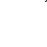

Saved: Fig1a_TimeResponse_p1of3.png


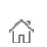

Saved: Fig1b_TimeResponse_p2of3.png


Saved: Fig1c_TimeResponse_p3of3.png



%% ── 7. FIGURES 1a, 1b, 1c: 10 representative step responses across 3 pages
%   Page 1 (2x2): scenarios 1-4
%   Page 2 (2x2): scenarios 5-8
%   Page 3 (1x2): scenarios 9-10
sel    = round(linspace(1, N, 10));
colors = {[0 0.447 0.741], [0.850 0.325 0.098]};

groups        = {sel(1:4), sel(5:8), sel(9:10)};
layouts       = {[2 2],    [2 2],    [1 2]};
fig_names     = {'Fig1a_TimeResponse_p1of3.png', ...
                 'Fig1b_TimeResponse_p2of3.png', ...
                 'Fig1c_TimeResponse_p3of3.png'};
fig_titles    = {'Step Response: DDPG-PID vs. Conv. PID — Page 1 of 3 (Scenarios 1–4 of 10)', ...
                 'Step Response: DDPG-PID vs. Conv. PID — Page 2 of 3 (Scenarios 5–8 of 10)', ...
                 'Step Response: DDPG-PID vs. Conv. PID — Page 3 of 3 (Scenarios 9–10 of 10)'};
fig_positions = {[50 50 1000 900], [50 50 1000 900], [50 50 1000 480]};

for g = 1:numel(groups)
    idx_group = groups{g};
    rows = layouts{g}(1);
    cols = layouts{g}(2);

    figH = figure('Name', fig_titles{g}, 'Color','w', 'Position', fig_positions{g});
    tiledlayout(rows, cols, 'TileSpacing','compact', 'Padding','compact');

    for kk = 1:numel(idx_group)
        i = idx_group(kk);
        nexttile;
        hD = []; hC = [];
        if ~isempty(t_all_ddpg{i})
            hD = plot(t_all_ddpg{i}, h_all_ddpg{i}, 'Color',colors{1}, ...
                'LineWidth',1.8,'DisplayName','DDPG-PID');
            hold on;
        end
        if ~isempty(t_all_conv{i})
            hC = plot(t_all_conv{i}, h_all_conv{i}, 'Color',colors{2}, ...
                'LineWidth',1.8,'LineStyle','--','DisplayName','Conv. PID');
            hold on;
        end
        yline(target_heights(i),        'k--','LineWidth',1.0,'HandleVisibility','off');
        yline(target_heights(i) * 1.05, 'k:', 'LineWidth',0.8,'HandleVisibility','off');
        yline(target_heights(i) * 0.95, 'k:', 'LineWidth',0.8,'HandleVisibility','off');
        hold off;
        title(sprintf('S%d: %.1f to %.1f m', i, start_heights(i), target_heights(i)), ...
            'FontSize',11);
        xlabel('Time (s)','FontSize',10); ylabel('Height (m)','FontSize',10);
        ylim([0 20]); grid on; box on;
        % Show legend on every tile (improves clarity on smaller per-page grids)
        legend_handles = [hD, hC];
        legend_handles = legend_handles(isgraphics(legend_handles));
        if ~isempty(legend_handles)
            legend(legend_handles,'Location','southeast','FontSize',8);
        end
    end
    sgtitle(fig_titles{g}, 'FontSize',12,'FontWeight','bold');
    exportgraphics(figH, fig_names{g}, 'Resolution',300);
    fprintf('Saved: %s\n', fig_names{g});
end


%% ── 8. FIGURE 2: Box plots ───────────────────────────────────────────────
fig2 = figure('Name','Box Plots','Color','w','Position',[50 50 1300 550]);
tiledlayout(1,5,'TileSpacing','compact','Padding','compact');
for m = 1:nM
    fd = metricFields{m};
    nexttile;
    data_mat = [DDPG.(fd), Conv.(fd)];
    bp = boxplot(data_mat,{'DDPG-PID','Conv. PID'},'Width',0.5,'Symbol','o');
    set(bp,'LineWidth',1.5);
    h_boxes = findobj(gca,'Tag','Box');
    patch(get(h_boxes(2),'XData'),get(h_boxes(2),'YData'),colors{1},'FaceAlpha',0.35);
    patch(get(h_boxes(1),'XData'),get(h_boxes(1),'YData'),colors{2},'FaceAlpha',0.35);
    title(metricLabels{m},'FontSize',9,'FontWeight','bold');
    grid on; box on;
end

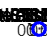

sgtitle('Performance Distributions Across 50 Test Scenarios','FontSize',11,'FontWeight','bold');
exportgraphics(fig2,'Fig2_MetricsBoxplot.png','Resolution',300);

fprintf('Saved: Fig2_MetricsBoxplot.png\n');

Saved: Fig2_MetricsBoxplot.png


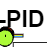


%% ── 9. FIGURE 3: ISE scatter ─────────────────────────────────────────────
fig3 = figure('Name','ISE Scatter','Color','w','Position',[50 50 650 550]);
scatter(Conv.ISE, DDPG.ISE, 60, abs(target_heights - start_heights), ...
    'filled','MarkerEdgeColor','k','LineWidth',0.5);
cb3 = colorbar; colormap(gca,'turbo');
cb3.Label.String = 'Step Size (m)';
hold on;
max_ise = max([Conv.ISE; DDPG.ISE]);
plot([0 max_ise],[0 max_ise],'k--','LineWidth',1.2,'DisplayName','Equal performance');
hold off;
xlabel('ISE — Conventional PID','FontSize',11);
ylabel('ISE — DDPG-PID','FontSize',11);
title('Per-Scenario ISE: DDPG-PID vs. Conventional PID','FontSize',11,'FontWeight','bold');
legend('Location','northwest','FontSize',9);
grid on; box on;
exportgraphics(fig3,'Fig3_ScatterISE.png','Resolution',300);

fprintf('Saved: Fig3_ScatterISE.png\n');

Saved: Fig3_ScatterISE.png



%% ── 10. FIGURE 4: Mean ± SD bar charts ──────────────────────────────────
fig4 = figure('Name','Mean Metrics','Color','w','Position',[50 50 1000 480]);
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

nexttile;
flds1 = {'RiseTime','SettlingTime'};
lbls1 = {'Rise Time','Settling Time'};
bdat1 = [cellfun(@(f) summary.(f).DDPG_mean, flds1); ...
         cellfun(@(f) summary.(f).Conv_mean,  flds1)]';
hb1 = bar(bdat1,'grouped');
hb1(1).FaceColor = colors{1}; hb1(2).FaceColor = colors{2};
hold on;
gw = 0.8;
for bb = 1:2
    xe  = (1:2) - gw/2 + (2*bb-1)*gw/4;
    if bb==1
        errs = cellfun(@(f) summary.(f).DDPG_std, flds1);
    else
        errs = cellfun(@(f) summary.(f).Conv_std, flds1);
    end
    errorbar(xe, bdat1(:,bb)', errs, 'k.','LineWidth',1.2);
end
hold off;
set(gca,'XTickLabel',lbls1,'FontSize',10);
ylabel('Time (s)'); title('Temporal Metrics (Mean \pm SD)','FontWeight','bold');
legend('DDPG-PID','Conv. PID','Location','northwest'); grid on; box on;

nexttile;
flds2 = {'Overshoot','SS_Error','ISE'};
lbls2 = {'Overshoot (%)','SS Error (m)','ISE'};
bdat2 = [cellfun(@(f) summary.(f).DDPG_mean, flds2); ...
         cellfun(@(f) summary.(f).Conv_mean,  flds2)]';
hb2 = bar(bdat2,'grouped');
hb2(1).FaceColor = colors{1}; hb2(2).FaceColor = colors{2};
hold on;
for bb = 1:2
    xe = (1:3) - gw/2 + (2*bb-1)*gw/4;
    if bb==1
        errs = cellfun(@(f) summary.(f).DDPG_std, flds2);
    else
        errs = cellfun(@(f) summary.(f).Conv_std, flds2);
    end
    errorbar(xe, bdat2(:,bb)', errs, 'k.','LineWidth',1.2);
end
hold off;
set(gca,'XTickLabel',lbls2,'FontSize',10);
ylabel('Metric Value'); title('Error Metrics (Mean \pm SD)','FontWeight','bold');
legend('DDPG-PID','Conv. PID','Location','northwest'); grid on; box on;

sgtitle('Comparative Mean Performance: N=50 Scenarios','FontSize',11,'FontWeight','bold');
exportgraphics(fig4,'Fig4_BarMeans.png','Resolution',300);

fprintf('Saved: Fig4_BarMeans.png\n');

Saved: Fig4_BarMeans.png


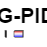


%% ── 11. FIGURE 5: % Improvement heatmap ─────────────────────────────────
[~, sort_idx] = sort(abs(target_heights - start_heights));
pct_mat = nan(nM, N);
for m = 1:nM
    fd = metricFields{m};
    for i = 1:N
        if ~isnan(DDPG.(fd)(i)) && ~isnan(Conv.(fd)(i)) && Conv.(fd)(i) ~= 0
            pct_mat(m,i) = (Conv.(fd)(i) - DDPG.(fd)(i)) / Conv.(fd)(i) * 100;
        end
    end
end

fig5 = figure('Name','Heatmap','Color','w','Position',[50 50 1300 380]);
imagesc(pct_mat(:, sort_idx));
colormap(redblue_map(256));
clim([-100 100]);
cb5 = colorbar;
cb5.Label.String = '% Improvement (positive = DDPG-PID better)';
set(gca,'YTick',1:nM,'YTickLabel',metricLabels,'FontSize',9);
xlabel('Scenarios sorted by step size (small to large)','FontSize',10);
title('Per-Metric % Improvement of DDPG-PID over Conventional PID (N=50)', ...
    'FontSize',10,'FontWeight','bold');
exportgraphics(fig5,'Fig5_ImprovementHeatmap.png','Resolution',300);

fprintf('Saved: Fig5_ImprovementHeatmap.png\n');

Saved: Fig5_ImprovementHeatmap.png



%% ── 12. FIGURE 6: Metrics vs step size ──────────────────────────────────
step_sizes = abs(target_heights - start_heights);
flds6  = {'RiseTime','SettlingTime','Overshoot','ISE'};
ylbls6 = {'Rise Time (s)','Settling Time (s)','Overshoot (%)','ISE'};

fig6 = figure('Name','Metrics vs Step Size','Color','w','Position',[50 50 1100 780]);
tiledlayout(2,2,'TileSpacing','compact','Padding','compact');
for m = 1:4
    fd = flds6{m};
    nexttile;
    % Capture scatter handles explicitly so legend reliably shows BOTH markers.
    hD = scatter(step_sizes, DDPG.(fd), 55, colors{1}, 'o', 'filled', ...
        'MarkerEdgeColor','w','LineWidth',0.5,'DisplayName','DDPG-PID');
    hold on;
    hC = scatter(step_sizes, Conv.(fd), 55, colors{2}, 'd', 'filled', ...
        'MarkerEdgeColor','w','LineWidth',0.5,'DisplayName','Conv. PID');

    valid = ~isnan(DDPG.(fd)) & ~isnan(Conv.(fd));
    xs = linspace(min(step_sizes), max(step_sizes), 100);
    plot(xs, polyval(polyfit(step_sizes(valid), DDPG.(fd)(valid),1), xs), ...
        '-','Color',colors{1},'LineWidth',1.5,'HandleVisibility','off');
    plot(xs, polyval(polyfit(step_sizes(valid), Conv.(fd)(valid),1), xs), ...
        '--','Color',colors{2},'LineWidth',1.5,'HandleVisibility','off');
    hold off;
    xlabel('Step Size (m)','FontSize',9);
    ylabel(ylbls6{m},'FontSize',9);
    title(ylbls6{m},'FontSize',9,'FontWeight','bold');
    if m==1
        % Pass handles explicitly so MATLAB renders BOTH marker icons in the legend
        legend([hD hC],{'DDPG-PID','Conv. PID'}, ...
            'Location','northwest','FontSize',8);
    end
    grid on; box on;
end
sgtitle('Performance Metrics vs. Step Size Across 50 Scenarios','FontSize',11,'FontWeight','bold');
exportgraphics(fig6,'Fig6_OperatingRange.png','Resolution',300);

fprintf('Saved: Fig6_OperatingRange.png\n');

Saved: Fig6_OperatingRange.png



fprintf('\nAll done. Files saved to: %s\n', pwd);


All done. Files saved to: C:\Users\HP\Desktop\BELLS\FINAL YEAR PROJECT\PROJECT MATLAB\CURRENT WORK



%% ── Helper: red-blue colormap ────────────────────────────────────────────


function cmap = redblue_map(n)
    half = floor(n/2);
    cmap = [[linspace(0.2,1,half)'; ones(n-half,1)], ...
            [linspace(0.2,1,half)'; linspace(1,0.2,n-half)'], ...
            [ones(half,1);          linspace(1,0.2,n-half)']];
end
